# 2.4 Péndulo invertido linealizado

Partimos de las ecuaciones


$$\dot x_1 = x_2 \\ 
\dot x_2 = gl \sin x_1 - \frac{b}{ml} x_2$$


donde $x_1 =\theta$ y $x_1 =\dot{\;\theta }$. 

**a)**

**b)**

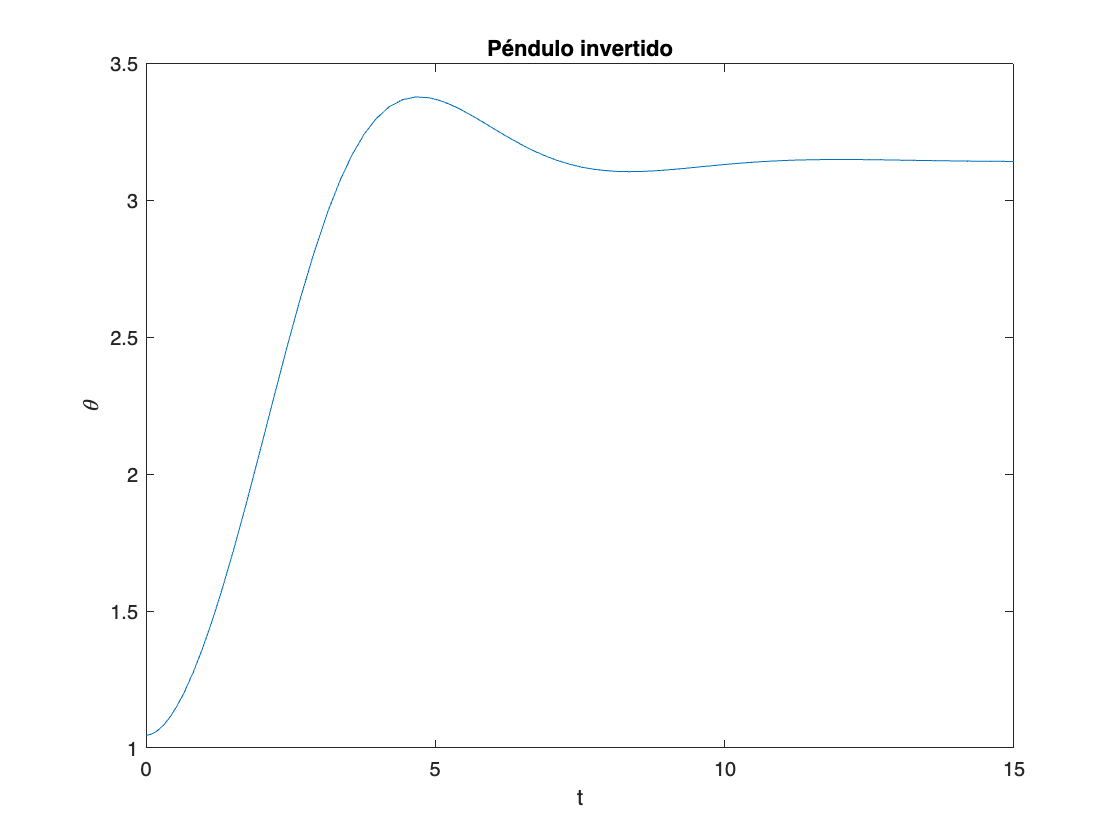

clear; close all; clc; clf;

[m, g, l, b] = deal(1);

tspan = [0, 15];

x0 = [pi/3; 0];
dx0 = [0; 0]; %Perturbación de la situación inicial

%Simulación del sistema original

[t, x] = ode45(@(t, x)invpendulum(t, x, m, g, l, b), tspan, x0 + dx0);

plot(t, x(:, 1));

xlabel("t");
ylabel("\theta");
title("Péndulo invertido");

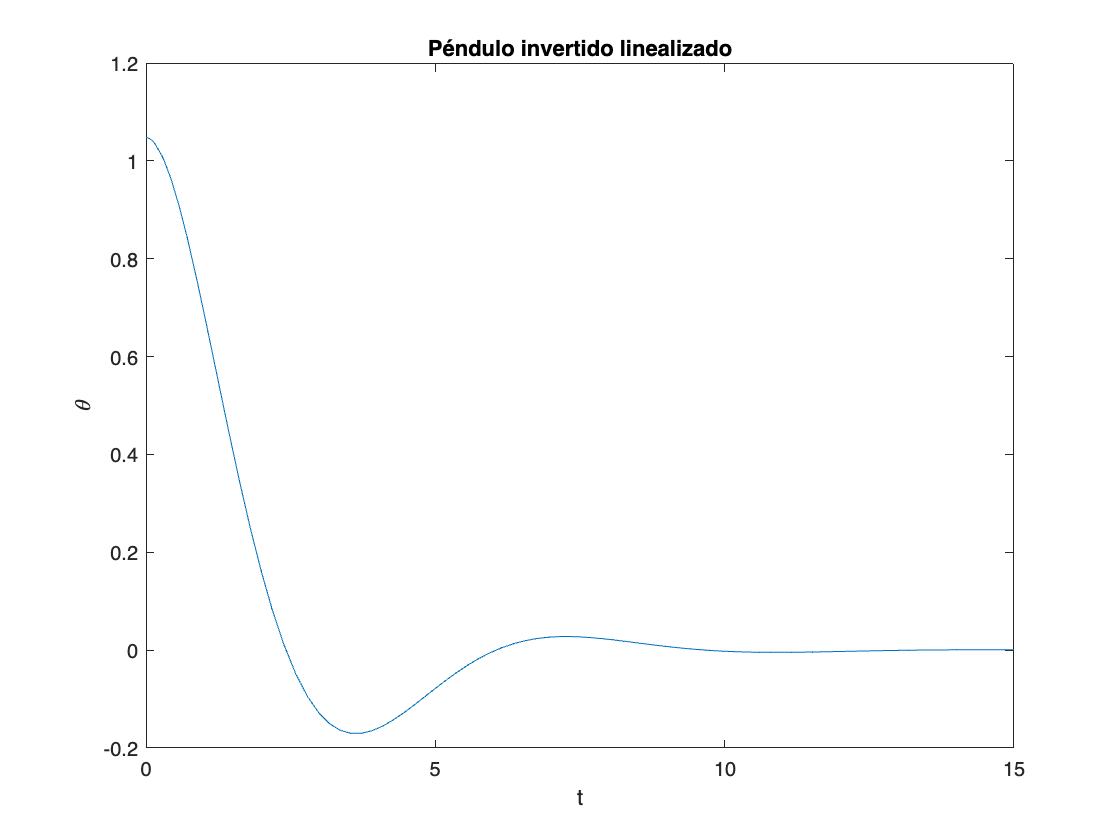


%Linealización

[t, x] = ode45(@(t, dx)linvpendulum(t, dx, m, g, l, b), tspan, x0 + dx0);

plot(t, x(:, 1));
xlabel("t");
ylabel("\theta");
title("Péndulo invertido linealizado");

function xdot = invpendulum(t, x, m, g, l, b)
    xdot(1, 1) = x(2, 1);
    xdot(2, 1) = g/l * sin(x(1, 1)) - b/(m * l) * x(2, 1);
end

%{
function xlin = invpendulumlin(t, x, m, g, l, b)
    
    lambda1 = (- b + (b^2 + 4 * g * m^2 * l)^.5)/(2 * m * l);
    lambda2 = (- b - (b^2 + 4 * g * m^2 * l)^.5)/(2 * m * l);

    xlin(1, 1) = pi + exp(lambda1 * t) * x(1, 1);
    xlin(2, 1) = exp(lambda2 * t) * x(2, 1);
    
end
%} 

%Linealizado en torno a (pi, 0)
function dxlin = linvpendulum(t, dx, m, g, l, b)
    dxlin(1, 1) = dx(2, 1); %Esta nos queda igual que en la original
    dxlin(2, 1) = - g * l * dx(1, 1) - b / (m * l) * dx(2, 1);
end